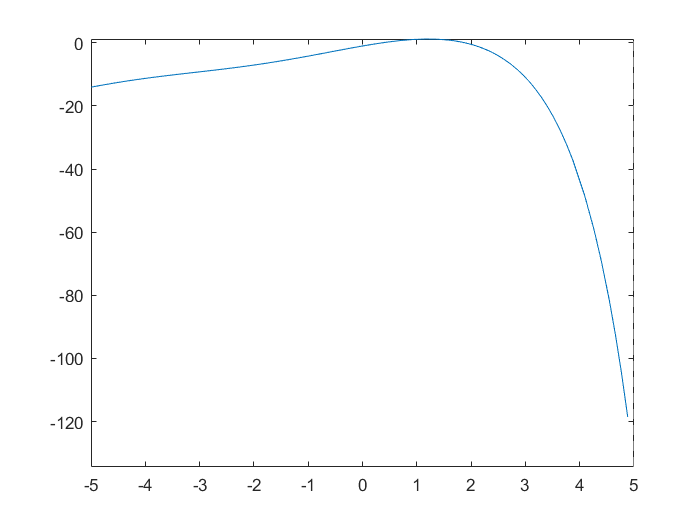

format long
syms x a b
f(x) = 3*x + sin(x)-exp(x);
fplot(f, [-5 5]);

digitsOld = digits(6);     % For getting 6 significant digits

a = 0; b = 1;
M = [];
M(1) = a; M(2) = b;
i = 3;
while(abs(double(f(M(i-1))-f(M(i-2))))> 1e-6)
    
    X = vpa(b - f(b)*(b-a)/(f(b)-f(a)))
   M(i) = X;
    if((f(M(i)*f(a))<0))
        b = M(i);
    else 
        a = M(i);
    end
     if i>=5
        if(abs(M(i)-M(i-1))> abs(M(i-1)-M(i-2)))
            disp('Either diverging or cyclic')
            break
        end
    end
    i = i + 1;
end

$$X = 0.47099$$

$$X = 0.372277$$

$$X = 0.361598$$

$$X = 0.360537$$

$$X = 0.360433$$

$$X = 0.360423$$

$$X = 0.360422$$

$$X = 0.360422$$

M

M =                    0   1.000000000000000   0.470989594596304   0.372277052235077   0.361597744029446   0.360537403486802   0.360433076398955   0.360422820886654   0.360421812843491   0.360421713760950



eqns = f(x)==0;
Exact_Solution = vpasolve(eqns,x)

$$Exact\_Solution = 0.360422$$

Error = abs(Exact_Solution(1) - M(3:i-1)');
Relative_Error = Error/Exact_Solution(1);
Table = vpa([M(3:i-1)' Error Relative_Error])

$$Table = \left(\begin{array}{ccc} 0.47099 & 0.110568 & 0.306774\\ 0.372277 & 0.0118554 & 0.0328931\\ 0.361598 & 0.00117606 & 0.00326302\\ 0.360537 & 0.000115723 & 0.000321077\\ 0.360433 & 0.0000113959 & 0.0000316183\\ 0.360423 & 0.00000114041 & 0.0000031641\\ 0.360422 & 1.32367e-7 & 3.67257e-7\\ 0.360422 & 3.32849e-8 & 9.235e-8 \end{array}\right)$$

% Order of Convergence
format long
n = length(Error)-1

n =      7


r = log(Error(1:n));
s = log(Error(2:n+1));
sumr=0.00; sums = 0.00; sumr2 = 0.00; sumrs=0.00;
for i = 1:n
    sumr = sumr+r(i);
    sumr2 = sumr2 + r(i)^2;
    sums = sums + s(i);
    sumrs = sumrs + r(i)*s(i);
end
Order_of_Convergence = (sumr*sums-n*sumrs)/(sumr^2-n*sumr2)

$$Order\_of\_Convergence = 0.955304$$